A certain metabolite  **A** is converted to  **B** at a rate of  **k1** =0.5 min-1 in a cell. The reverse reaction occurs at a rate of  **k2** =0.3 min ^-1 . Initially, the concentrations of  **A** and  **B** are 700 and 500 nM, respectively.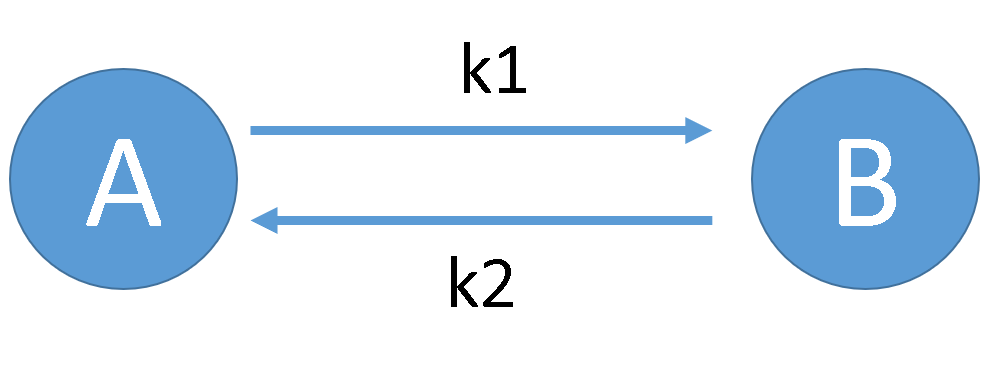

**A. Solve the system of ODEs for the concentrations of A and B over time. Plot concentrations of A and B over time.**

clear all;
k1=0.5;
k2=0.3;
syms b(t) a(t)
eqn = [ diff(a(t),t) == -k1*a(t) + k2*b(t),   diff(b(t),t) == k1*a(t) - k2*b(t) ]

$$eqn = \left(\begin{array}{cc} \frac{\partial }{\partial t}a\left(t\right)=\frac{3\,b\left(t\right)}{10}-\frac{a\left(t\right)}{2} & \frac{\partial }{\partial t}b\left(t\right)=\frac{a\left(t\right)}{2}-\frac{3\,b\left(t\right)}{10} \end{array}\right)$$

cond = [ a(0) == 700, b(0) == 500 ]

$$cond = \left(\begin{array}{cc} a\left(0\right)=700 & b\left(0\right)=500 \end{array}\right)$$

sol = dsolve(eqn, cond)

sol = struct with fields:
    b: [1×1 sym]
    a: [1×1 sym]


at = sol.a

$$at = 250\,{\mathrm{e}}^{-\frac{4\,t}{5}}+450$$

bt = sol.b

$$bt = 750-250\,{\mathrm{e}}^{-\frac{4\,t}{5}}$$

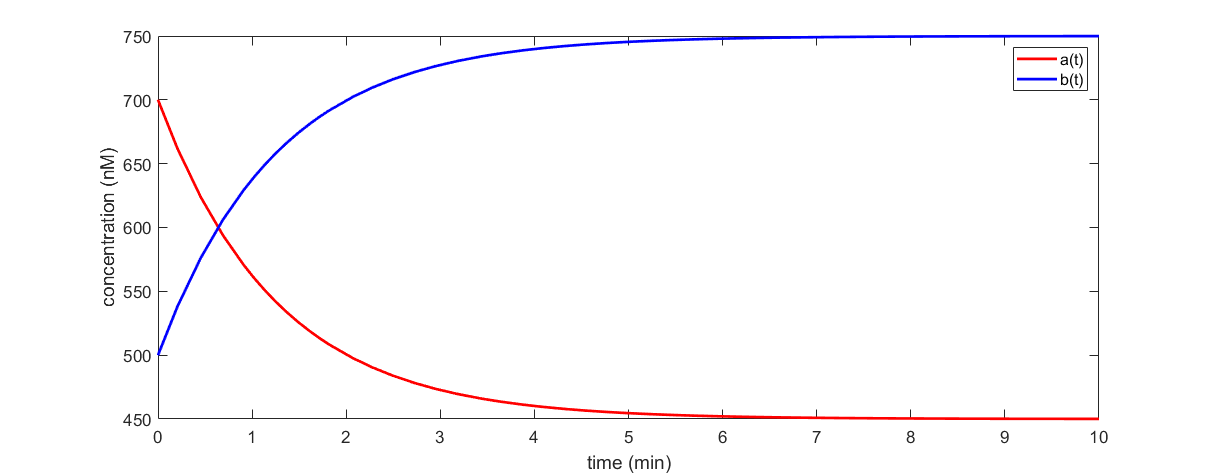

fplot(at, [0,10], 'displayname', 'a(t)', 'color','red', 'linewidth',2)
hold on;
fplot(bt, [0,10], 'displayname', 'b(t)', 'color','blue', 'linewidth',2)
hold off
xlabel('time (min)')
ylabel('concentration (nM)')
legend show

**B. At what time are the concentrations of the 2 metabolites equal?**

tequal = solve(at == bt, t, 'Real', true)

$$tequal = -\frac{5\,\log\left(\frac{3}{5}\right)}{4}$$

double(tequal)

ans = 0.6385

**C. What are the steady-state concentrations of A and B?**

limit(at, t, sym(inf))

$$ans = 450$$


limit(bt, t, sym(inf))

$$ans = 750$$